# Dialog: Table Selection

## Create the dialog

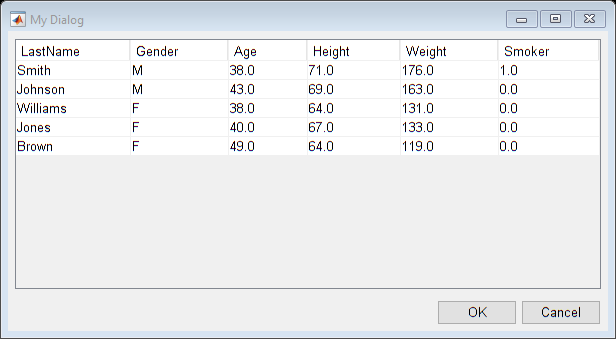

filename = fullfile(matlabroot,'examples','matlab','myCsvTable.dat');
tableData = readtable(filename);

d = uiw.dialog.TableSelection(...
    'Title','My Dialog',...
    'DataTable',tableData,...
    'SelectedRows',1,...
    'MultiSelect',true);


% Hold down CTRL to select multiple rows with the mouse.

% If you did not want a modal dialog (modal is the default):
% d.WindowStyle = 'normal'; %or use ...,'WindowStyle','normal') on construction

## Wait for output

% To wait for output and get a result:
%[out, action] = d.waitForOutput()